# **Ejemplo 2 de Árboles de Decisión : Entrenar un arbol**

%% Ejemplo de Árbol de Decisión para Clasificación de Legumbres
clear all, close all, clc

% Cargar la tabla de legumbres desde CSV
T = readtable('../data/data_legumbres.csv');

caracteristicas = {'Area', 'Eccentricity', 'Circularidad', ...
                   'MeanR', 'MeanG', 'MeanB'};

%caracteristicas = {'Area','MeanR', 'MeanG', 'MeanB'};
data = T(:, caracteristicas);
clase = T(:, {'Clase'});

% Convertir a arrays
X = table2array(data);
Y = table2array(clase);

**Mostrar un resumen de los datos**

fprintf('Número de muestras: %d\n', size(X,1));

Número de muestras: 611


fprintf('Número de clases: %d\n\n', numel(unique(Y)));

Número de clases: 3



**Dividir el conjunto de datos (70% entrenamiento, 30% prueba)**

cv = cvpartition(Y, 'HoldOut', 0.3);
X_train = X(training(cv), :);
Y_train = Y(training(cv));
X_test  = X(test(cv), :);
Y_test  = Y(test(cv));

**Entrenar el modelo de árbol de decisión**

treeModel = fitctree(X_train, Y_train, 'MaxNumSplits',5,'MinParent',15,'MinLeafSize',1,'SplitCriterion', 'gdi');
save('models/modLegumbres_desicionTree.mat', 'treeModel');


**Visualizar el árbol**

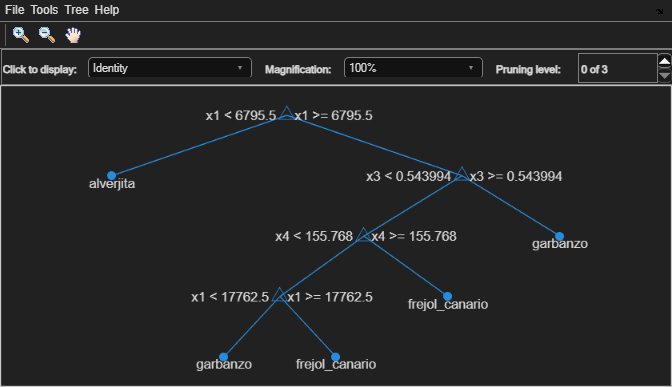

view(treeModel, 'Mode', 'graph')